# Basic Tight-Binding Theory - Part 2

## Example 2: The square lattice

For the square lattice we expand the linear chain in two dimensions. The primitive vectors are 


$$\[
\mathbf{a}_1 = (a,0,0),\ \mathbf{a}_2 = (0,-a,0)
\]
\[
\mathbf{b}_1 = (2\pi/a,0,0),\ \mathbf{a}_2 = (0,-2\pi/a,0)
\]$$


The first Brillouin zone is 


$$k_x\in [-\pi/a,+\pi/a],\ k_y\in [-\pi/a,+\pi/a]$$


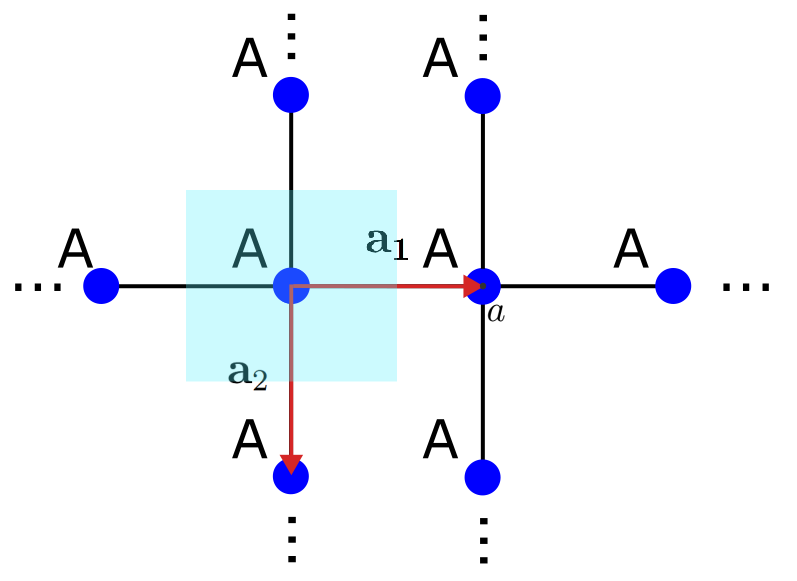

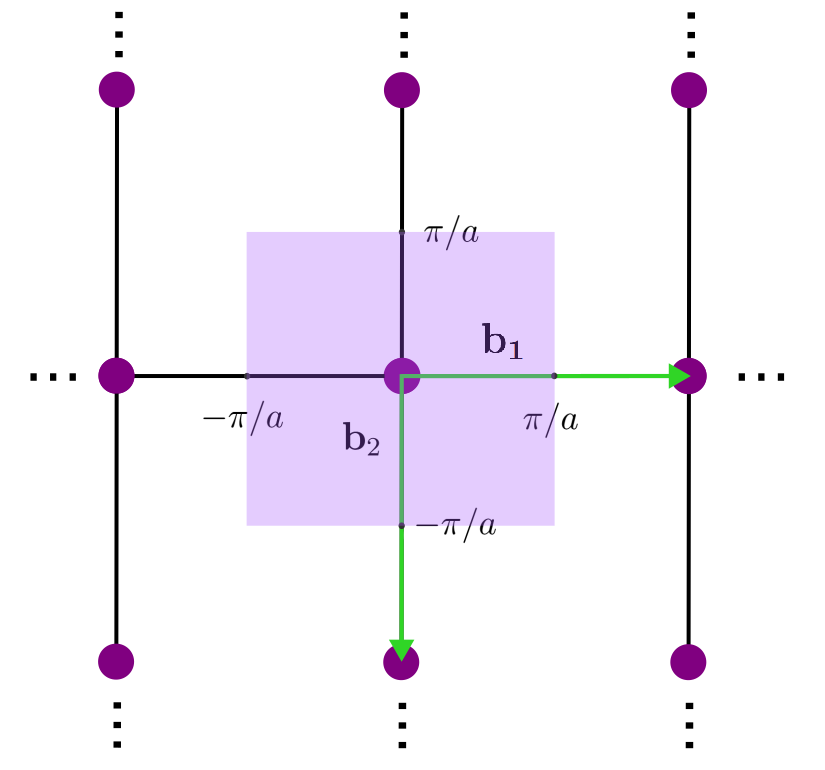

Now, we define the NN vectors $\{\mathbf{d}_n\}$, for which there are four NNs


$$\[
\mathbf{d}_1 = (a,0,0),\ \mathbf{d}_2 = (-a,0,0) = - \mathbf{d}_1,\ \mathbf{d}_3 = (0,a,0),\ \mathbf{d}_4 = (0,-a,0) = -\mathbf{d}_3
\]$$


Writing down the Hamiltonian 


$$\[
H = \sum_i u c_i^\dag c_i + \biggl(\sum_{i,j} t  c_i^\dag c_j + \textbf{h.c.}\biggl)
\]$$


Like with the linear chain, changing basis to momentum space, we get


$$\[
H = u \sum_i \biggr[\frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} c_k^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_k e^{i(\mathbf{k}\cdot \mathbf{r}_i)} c_k\biggr] +
t \sum_{i,j} \biggl\{\biggr[\frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} c_k^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_{k'} e^{i(\mathbf{k'}\cdot \mathbf{r}_j)} c_{k'}\biggr] + \textbf{h.c.} \biggl\}
\]
\[
= \frac{u}{N} \sum_i (1) \sum_k  c_k^\dag c_k +
\frac{t}{N}  \sum_k\sum_{k'} \sum_i \biggl\{ c_k^\dag c_{k'} e^{-i(\mathbf{k}\cdot \mathbf{r}_i)}  \biggr[\sum_j e^{i(\mathbf{k'}\cdot \mathbf{r}_j)}\biggr] +  \textbf{h.c.} \biggl\}
\]$$


Noting that $\sum_i (1) = N$, and inserting $1 = e^{-i(\mathbf{k'}\cdot \mathbf{r}_i)} e^{i(\mathbf{k'}\cdot \mathbf{r}_i)}$, we have 


$$\[
\Rightarrow H = u \sum_k  c_k^\dag c_k +
\frac{t}{N}  \sum_k\sum_{k'} \sum_i \biggl\{ c_k^\dag c_{k'} e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}  \biggr[\sum_j e^{i\mathbf{k'}\cdot (\mathbf{r}_j-\mathbf{r}_i)}\biggr] +  \textbf{h.c.} \biggl\}
\]$$


Applying the NN approximation, and defining the $f(\mathbf{k})$ for the square lattice; each site $i$ is connected to four other sites $j$ by the NN vectors $\{\mathbf{d}_n\}$.


$$\[
f(\mathbf{k}) \equiv \sum_{n=1}^{4} e^{i(\mathbf{k}\cdot \mathbf{d}_n)}
\]

\[
\Rightarrow H = u \sum_k  c_k^\dag c_k +
\frac{t}{N}  \sum_k\sum_{k'} \sum_i \biggl\{ c_k^\dag c_{k'} e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}  f(\mathbf{k'}) +  \textbf{h.c.} \biggl\}

=  \sum_k  c_k^\dag u c_k + \frac{t}{N}  \sum_k\sum_{k'} \biggl\{ c_k^\dag c_{k'} \biggr[\sum_i e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}\biggr]  f(\mathbf{k'}) +  \textbf{h.c.} \biggl\}
\]$$


Using the orthonormality relation, we get


$$\[
H = \sum_k  c_k^\dag u c_k + \frac{t}{N}  \sum_k\sum_{k'}  \biggl\{ c_k^\dag c_{k'} \bigr[N\delta_{kk'}\bigr]  \bigr[f(\mathbf{k'})\bigr] + \textbf{h.c.} \biggl\}

= \sum_k  c_k^\dag u c_k + t  \sum_k  \biggr[ c_k^\dag c_{k} f(\mathbf{k}) +  \textbf{h.c.} \biggr]
= \sum_k  c_k^\dag u c_k +  \sum_k  [c_k^\dag t f(\mathbf{k}) c_{k} + c_k^\dag t f^*(\mathbf{k}) c_{k}]
\]
\[
= \sum_k  c_k^\dag [u + 2 t f(\mathbf{k})] c_k;\ f(\mathbf{k})\in \mathbb{R}
\]$$


Evidently, the Hamiltonian in $k$-space yields: $\tilde{H} \equiv u + t f(\mathbf{k})$. In this case, the matrix $\tilde{H}$ is a one-by-one matrix, hence, the eigenvalue of such a matrix will be the matrix itself. 


$$\[
\det[\tilde{H} - \mathbb{I} E ] = 0 = \det[u+t f(\mathbf{k})- E ] = u+t f(\mathbf{k}) - E = 0
\]
\[
\Rightarrow E(\mathbf{k}) = u+t f(\mathbf{k}) = u + t \biggr[e^{i(\mathbf{k}\cdot \mathbf{d}_{1})}+ e^{-i(\mathbf{k}\cdot \mathbf{d}_{1})}+e^{i(\mathbf{k}\cdot \mathbf{d}_{3})}+ e^{-i(\mathbf{k}\cdot \mathbf{d}_{3})}\biggr]

= u + 2 t [\cos(\mathbf{k}\cdot \mathbf{d_1})+\cos(\mathbf{k}\cdot \mathbf{d_
3})] = u + 2 t [\cos(k_x a)+\cos(k_y a)];\ u\geq 0, t>0 
\]$$


In this example we want to do a high-symmetry plot of the band structure. By definition, the high-symmetry points of a square lattice of one site per unit cell in momentum space are


$$\[
\Gamma = (0,0,0);\ X = (\pi/a,0,0);\ M = (\pi/a,\pi/a,0).
\]$$


Hence, the k-path will be $\Gamma \rightarrow X \rightarrow M \rightarrow \Gamma$.

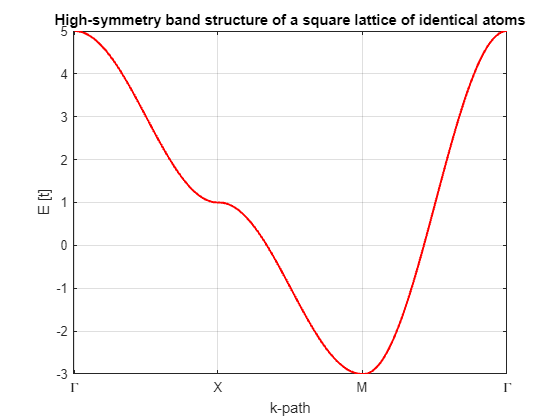


u = 1; % units of t

% Define the eigen-energy as a function of kxa and kya
E = @(kxa, kya) 1 + 2*(cos(kxa)+cos(kya)); % In units of t
N = 100; % number of points along each segment

% Define the high symmetry points
G = [0, 0]; % units of a
X = [pi, 0]; % units of a
M = [pi, pi]; % units of a

% Interpolate between points to create the path
k_Gamma_X = [linspace(G(1), X(1), N)', linspace(G(2), X(2), N)'];
k_X_M = [linspace(X(1), M(1), N)', linspace(X(2), M(2), N)'];
k_M_Gamma = [linspace(M(1), G(1), N)', linspace(M(2), G(2), N)'];

% Combine the paths
k_path = [k_Gamma_X; k_X_M; k_M_Gamma];

% Calculate the energy along the path
E_path = E(k_path(:,1), k_path(:,2));

% Plot the band structure over the high-symmetry path
clf;
plot(E_path, 'r', LineWidth=1.5);
xticks([1, N, 2*N, 3*N]); % Mark the high-symmetry points
xticklabels({'\Gamma', 'X', 'M', '\Gamma'});
xlabel ("k-path");
ylabel ("E [t]");
title('High-symmetry band structure of a square lattice of identical atoms');
grid on;

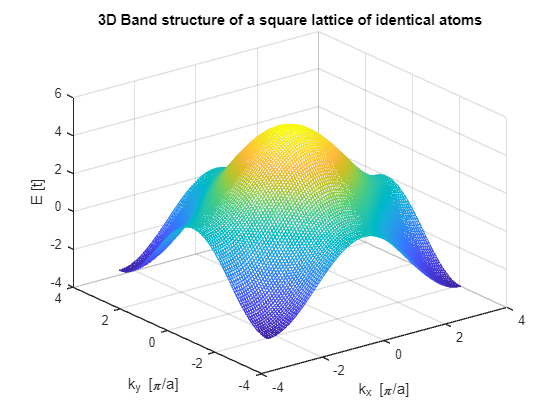

% Define the k-mesh 
[mkxa,mkya] = meshgrid(linspace(-pi,pi),linspace(-pi,pi));

% 3D plot of the eigen-energy function 
mesh(mkxa, mkya, E(mkxa, mkya));
xlabel ("k_x [\pi/a]");
ylabel ("k_y [\pi/a]");
zlabel ("E [t]");
title('3D Band structure of a square lattice of identical atoms');

For a square lattice of two distinct sites per unit cell, we need to change the primitive vectors; the unit cell will change since it needs to account for the other distinct site. The new primitive vectors are


$$\[
\mathbf{a}_1 = (a,a,0);\ \mathbf{a}_2 = (a,-a,0)\Rightarrow\ \mathbf{b}_1 = (\pi/a, \pi/a, 0);\ \mathbf{b}_2 = (\pi/a, -\pi/a, 0).
\]$$


The first Brillouin zone is 


$$\[
k_x\in [-\pi/a,+\pi/a],\ k_y\in [-\pi/a,+\pi/a]
\]$$


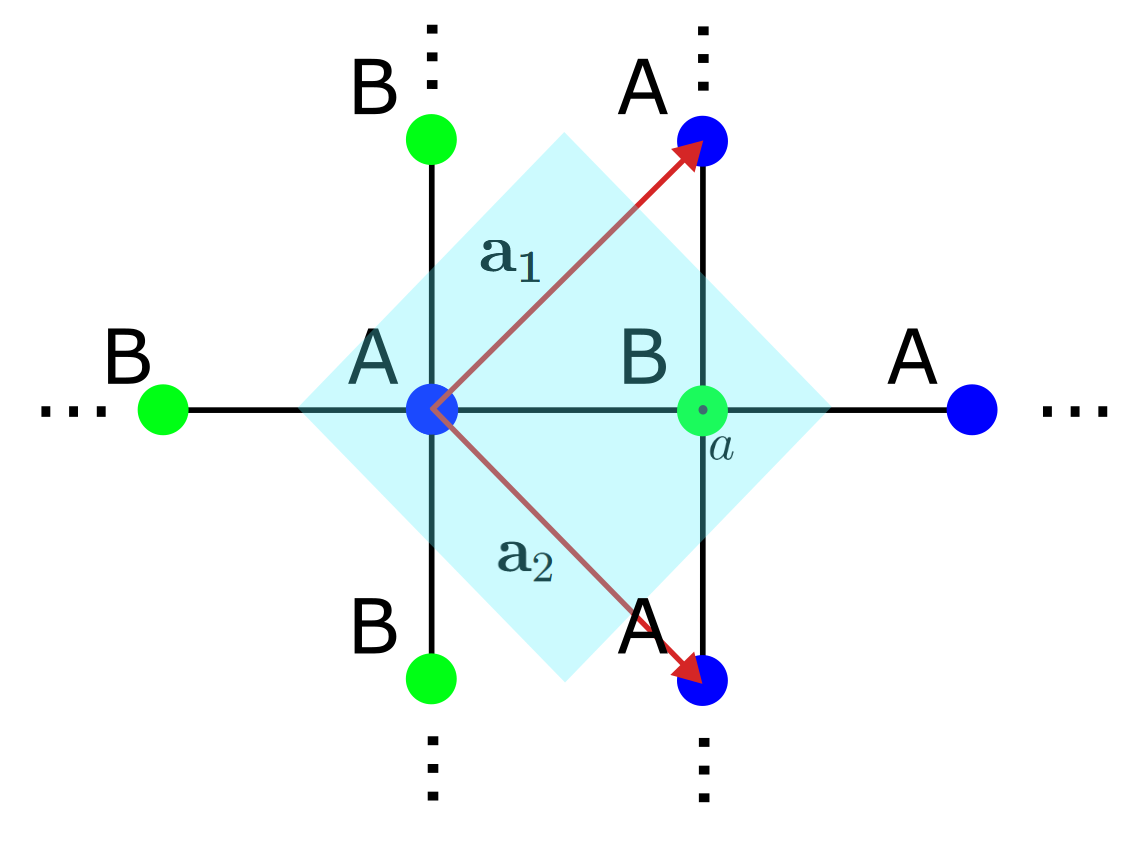

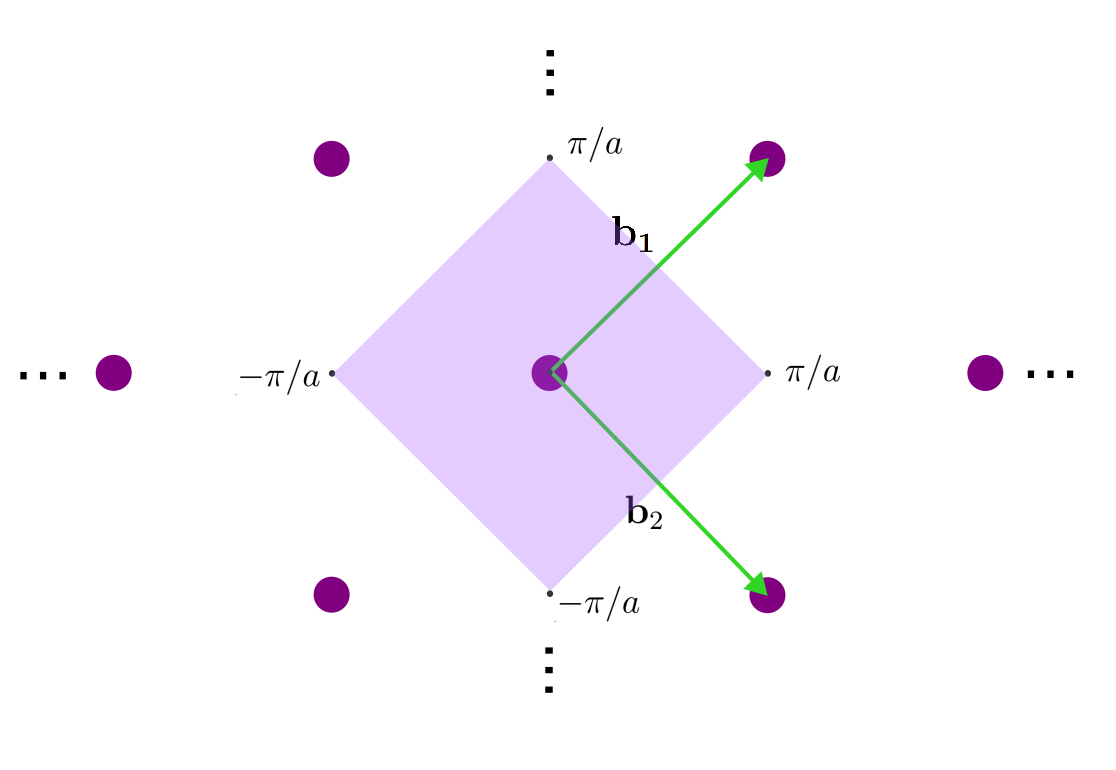

Finally, the NN vectors remain unchanged. Now, the Hamiltonian is written as


$$\[
H = u_A \sum_i a_i^\dag a_i + u_B \sum_j b_j^\dag b_j + t \sum_{i, j} (a_i^\dag b_j+ \textbf{h.c.})
\]$$


Like we did in the linear chain of two sites per unit cell, changing basis to $k$-space, and setting $u_A = u_B = u$, we get 


$$\[
H = \sum_k 
\left(
\begin{array}{cc}
    a_k^\dag & b_k^\dag
\end{array}
\right)
\left(
\begin{array}{cc}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\left(
\begin{array}{cc}
    a_k \\
    b_k
\end{array}
\right)
\]$$


such that


$$\[
f(\mathbf{k}) \equiv \sum_{n=1}^{4} e^{i(\mathbf{k}\cdot \mathbf{d}_n)} = e^{i(\mathbf{k}\cdot \mathbf{d}_1)} + e^{i(\mathbf{k}\cdot \mathbf{d}_2)} + e^{i(\mathbf{k}\cdot \mathbf{d}_3)} + e^{i(\mathbf{k}\cdot \mathbf{d}_4)}
= e^{i k_x a} + e^{-i k_x a} + e^{i k_y a} + e^{-i k_y a} = 2 [ \cos(k_x a)+ \cos(k_y a)]\]$$


Evidently,


$$

\[
\tilde{H} \equiv 
\left(
\begin{array}{cc}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\]
\[\Rightarrow \det(\tilde{H} - \mathbb{I}E)=
\det\left(
\begin{array}{cc}
    u-E & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u-E
\end{array}
\right)
= (E-u)^2 - t^2 |{f(\mathbf{k})}|^2 = (E-u)^2 - 4 t^2 [\cos(k_x a)+ \cos(k_y a)]^2 = 0
\]
\[
\therefore E(\mathbf{k}) = u\pm 2 t [\cos(k_x a)+ \cos(k_y a)] 
\]$$


By definition, the high-symmetry points of a square lattice of two sites per unit cell in momentum space are


$$\[
\Gamma = (0,0,0);\ X = (\pi/a,0,0);\ Y = (0,\pi/a,0).
\]$$


Hence, the k-path will be $\Gamma \rightarrow X \rightarrow Y \rightarrow \Gamma$.

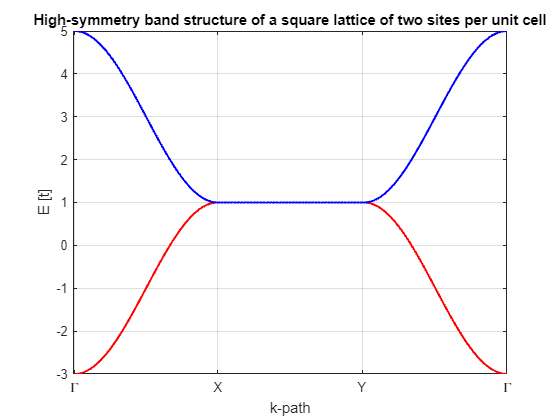

u = 1; % units of t

% Define the eigen-energy as a function of kxa and kya
E1 = @(kxa, kya) 1 - 2*(cos(kxa)+cos(kya)); % In units of t
E2 = @(kxa, kya) 1 + 2*(cos(kxa)+cos(kya)); % In units of t

N = 100; % number of points along each segment

% Define the high symmetry points
G = [0, 0]; % units of a
X = [pi, 0]; % units of a
Y = [0, pi]; % units of a


% Interpolate between points to create the path
k_Gamma_X = [linspace(G(1), X(1), N)', linspace(G(2), X(2), N)'];
k_X_Y = [linspace(X(1), Y(1), N)', linspace(X(2), Y(2), N)'];
k_Y_Gamma = [linspace(Y(1), G(1), N)', linspace(Y(2), G(2), N)'];

% Combine the paths
k_path = [k_Gamma_X; k_X_Y; k_Y_Gamma];

% Calculate the energy along the path
E_path1 = E1(k_path(:,1), k_path(:,2));
E_path2 = E2(k_path(:,1), k_path(:,2));

% Plot the band structure over the high-symmetry path
clf;
plot(E_path1, 'r', 'LineWidth', 1.5);
hold on;
plot(E_path2, 'b', 'LineWidth', 1.5);
xticks([1, N, 2*N, 3*N]); % Mark the high-symmetry points
xticklabels({'\Gamma', 'X', 'Y', '\Gamma'});
xlabel("k-path");
ylabel("E [t]");
title('High-symmetry band structure of a square lattice of two sites per unit cell');
grid on;
hold off;

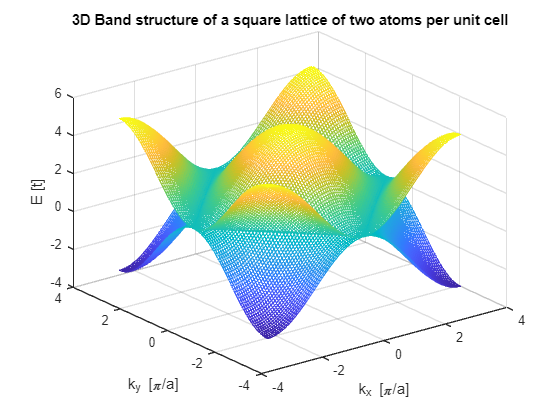

% Define the k-mesh 
[mkxa,mkya] = meshgrid(linspace(-pi,pi),linspace(-pi,pi));

% 3D plot of the eigen-energy function 
mesh(mkxa, mkya, E1(mkxa, mkya));
hold on;
mesh(mkxa, mkya, E2(mkxa, mkya));
xlabel ("k_x [\pi/a]");
ylabel ("k_y [\pi/a]");
zlabel ("E [t]");
title('3D Band structure of a square lattice of two atoms per unit cell');